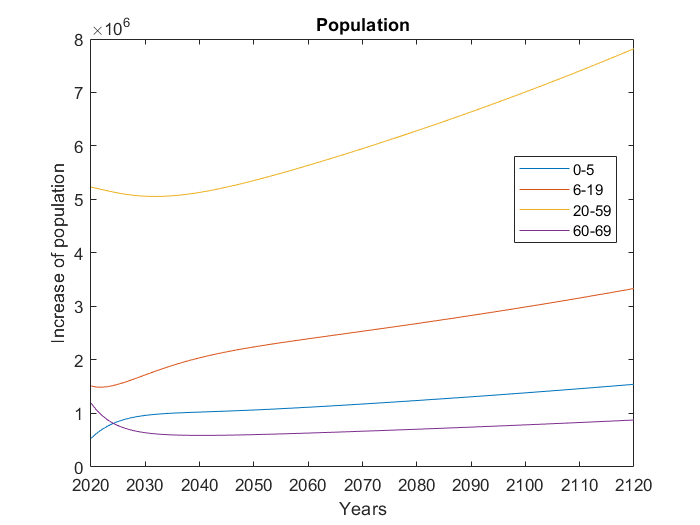

% Лабораторная работа №3
% Кирилло Дмитрий, 2 курс, 5 группа ММФ БГУ

clear;
clc

% =============================
% Задание 1
% =============================
t = 2020;
N1 = 536098;
N2 = 1513314;
N3 = 5232525;
N4 = 1193729;
dC = (2200/N1)*100;
dA = (155255/N4)*100;
b = (181620/N3)*100;
% =============================
% Прогресс
% =============================
% dC = 4;
% dA = 0.2;
% b = 25;
% =============================
% Стабильность
% =============================
% dC = 1.28;
% dA = 4.6;
% b = 2.7;
% =============================
% Регресс
% =============================
% -----------------------------
% Общего количества населения
% -----------------------------
% dC = 50;
% dA = 30;
% b = 0.6;
% -----------------------------
% По группам
% -----------------------------
%Дети до 5 лет 
% dC = 60;
% dA = 1;
% b = 1;
%Дети 6-19 лет
% dC = 50;
% dA = 1;
% b = 2;
%Старики 60-69 лет
% dC = 1;
% dA = 70;
% b = 1;
% -----------------------------
% Трудоспособного населения
% -----------------------------
% dC = 20;
% dA = 20;
% b = 1;

tRange = t + 100; 
N = [N1; N2; N3; N4];
L1 = [(1-(dC/100))*5/6 0 b/100 0];
L2 = [(1-(dC/100))*1/6 13/14 0 0];
L3 = [0 1/14 39/40 0];
L4 = [0 0 1/40 (1-(dA/100))*9/10];
L = [L1; L2; L3; L4];
for R= 1:100 
    N(:, R+1) = L*N(:,R);
end
plot((t:tRange), N)
title('Population')
xlabel('Years');
ylabel('Increase of population')
legend({'0-5','6-19','20-59','60-69'},'location','best')

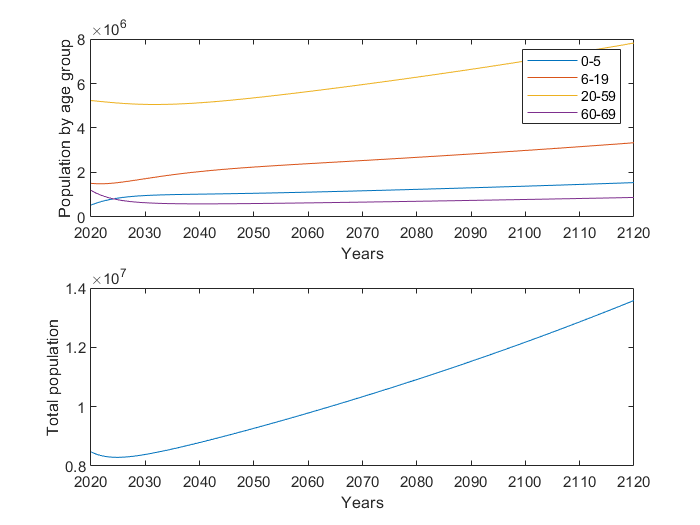

S = sum(N);
subplot(2,1,1)
plot(t:tRange,N)
xlabel('Years');
ylabel('Population by age group')
legend('0-5','6-19','20-59','60-69')
subplot(2,1,2)
plot(t:tRange,S)
xlabel('Years');
ylabel('Total population')